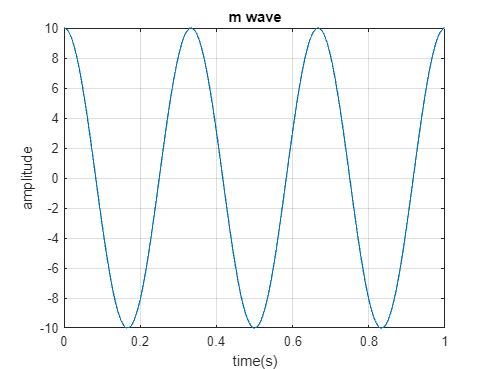

fs=1000;
t=0:1/fs:1;
fc=100;
fm=3;
ac=10;
am=10;
ka=0.7;
k1=2;
k2=0.2;

m=am*cos(2*pi*fm*t);
plot(t, m);
title("m wave");
xlabel("time(s)");
ylabel("amplitude");
grid on;

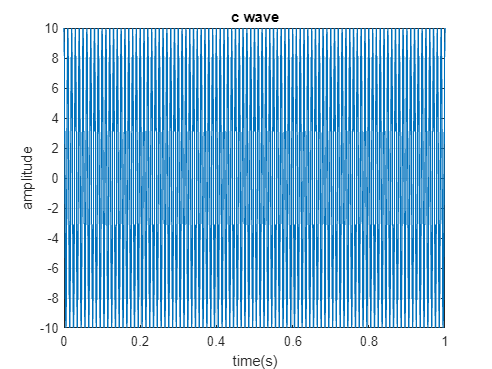


c=ac*cos(2*pi*fc*t);
plot(t, c);
title("c wave");
xlabel("time(s)");
ylabel("amplitude");
grid on;

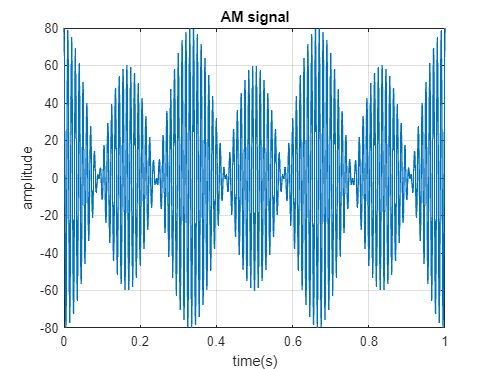


s=ac*(1+ka*m).*cos(2*pi*fc*t);
plot(t, s);
title("AM signal");
xlabel("time(s)");
ylabel("amplitude");
grid on;

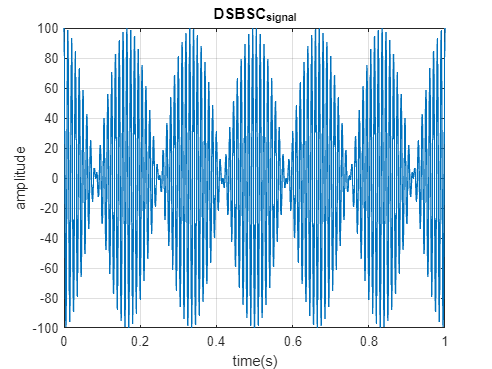


d=c.*m;
plot(t, dsbsc);
title("DSBSC_signal");
xlabel("time(s)");
ylabel("amplitude");
grid on;

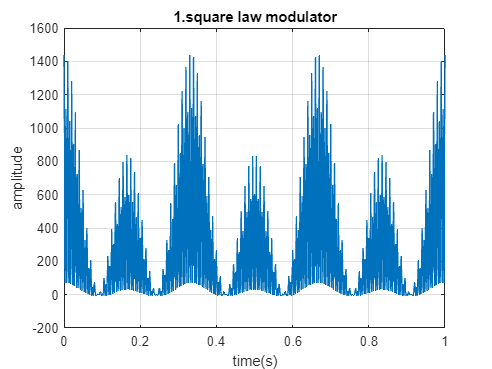


slm=k1*s+k2*(s.^2);
plot(t, slm);
title("1.square law modulator");
xlabel("time(s)");
ylabel("amplitude");
grid on;

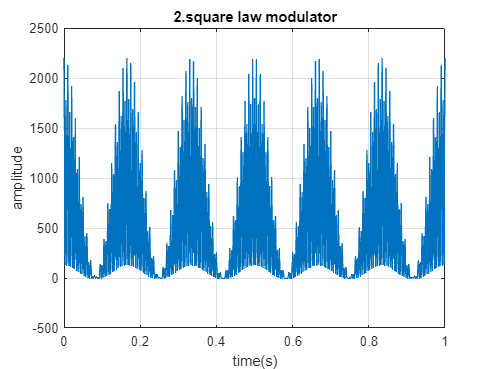


slm2=k1*d+k2*(d.^2);
plot(t, slm2);
title("2.square law modulator");
xlabel("time(s)");
ylabel("amplitude");
grid on;